# Ricker Wavelet

clear;
N = 1024; tmax = 1; dt = tmax/(N-1); fmax = 1/dt; fNq = fmax/2; 
df = fmax/(N-1); fc = 50; delay = tmax/2;
idx = -N/2:N/2-1;
t = idx * dt;
f = idx * df;
rickerT = (1 - 2* (pi * fc * t).^2).* exp(-(pi*fc*t).^2);
tmp = fft(rickerT)/N;
% figure;
% 
% xlim([-0.1, 0.1]);
% xlabel('t(s)'); ylabel('Amp');
% figure;
% plot(f(1:N/2)+fNq, abs(tmp(1:N/2)));
% xlim([0, fNq]);
% xlabel('freq(Hz)'); ylabel('Amp'); 

## Low Pass Filter

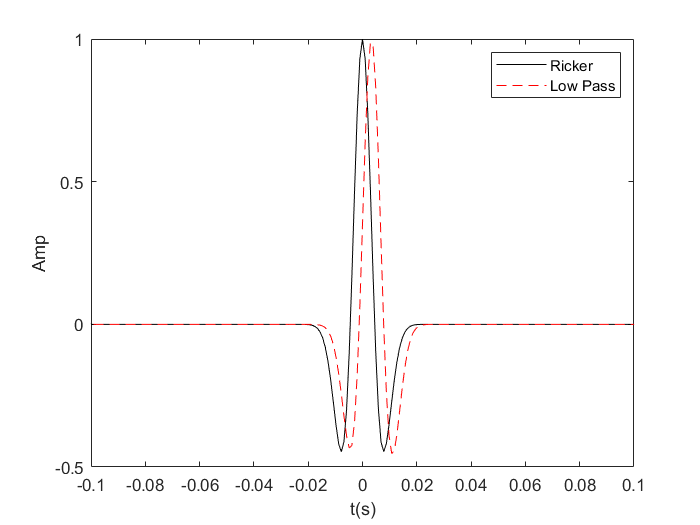

% fpass = 250 Hz; hence the 50 Hz Ricker should not be affected much.
fpass = 250;
butterOrder = 10;
lpFilt = designfilt('lowpassiir','FilterOrder', butterOrder, 'DesignMethod','butter', ...
         'HalfPowerFrequency',fpass/fmax, 'SampleRate', df);
tout = filter(lpFilt, rickerT);
tfilt = fft(tout)/N;
figure;
plot(t, rickerT, 'k');
hold on;
plot(t, tout, 'r--');
xlim([-0.1, 0.1]);
xlabel('t(s)'); ylabel('Amp');
legend('Ricker', 'Low Pass')

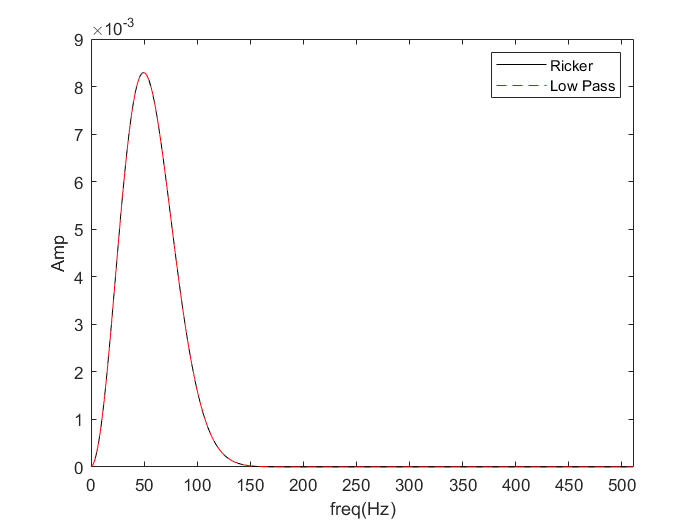

figure;
plot(f(1:N/2)+fNq, abs(tmp(1:N/2)), 'k');
hold on;
plot(f(1:N/2)+fNq, abs(tfilt(1:N/2)), 'r--');
legend('Ricker', 'Low Pass')
xlim([0, fNq]);
xlabel('freq(Hz)'); ylabel('Amp'); 

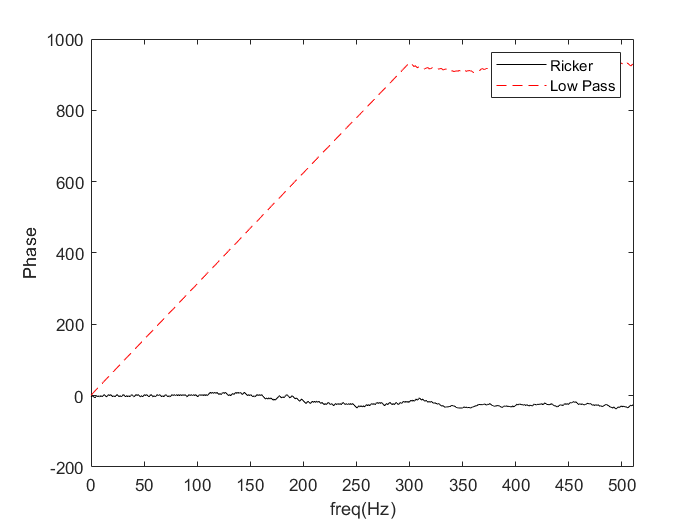

figure;
plot(f(1:N/2)+fNq, unwrap(angle(tmp(1:N/2))), 'k');
hold on;
plot(f(1:N/2)+fNq, unwrap(angle(tfilt(1:N/2))), 'r--');
legend('Ricker', 'Low Pass')
xlim([0, fNq]);
xlabel('freq(Hz)'); ylabel('Phase'); 